# Experieência 1 - LMS com Sinais Senoidais

## Gabriel Tavares Ferrarez - 10773801

## Guilherme Reis da Silva - 10773700

## 1 - Criação dos Sinais

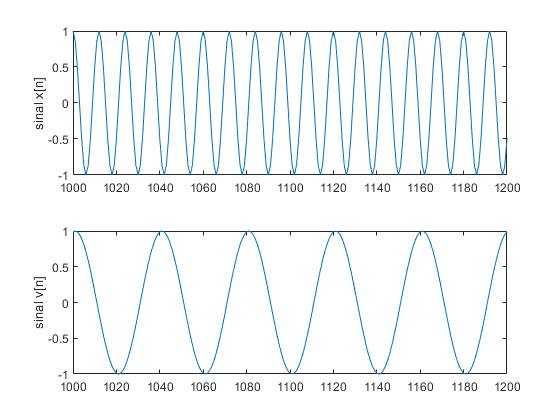

omega0 = pi/6;
omega1 = pi/20;
N = 10000;
n = (0:N-1);
x = sin(omega0*n);
v = cos(omega1*n);
h = [1 -0.5];

y = filter(h,1,x);
d = y + v;

figure()
subplot(2,1,1)
plot(x)
ylabel("sinal x[n]")
subplot(2,1,2)
plot(v)
ylabel("sinal v[n]")

subplot(2,1,1)
xlim([1000 1200])
ylim([-1.00 1.00])
subplot(2,1,2)
xlim([1000 1200])
ylim([-1.00 1.00])

## 2 - Implementação do LMS

    Como o sinal que se deseja remover possui apenas uma harmonica, o filtro deve possuir no mínimo 2 coeficientes reais. 

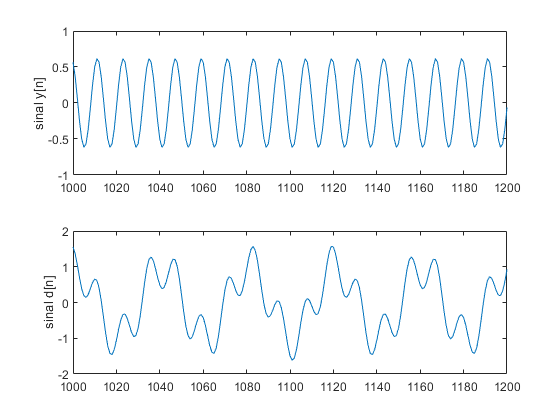

figure()
subplot(2,1,1)
plot(y)
ylabel("sinal y[n]")
subplot(2,1,2)
plot(d)
ylabel("sinal d[n]")

subplot(2,1,1)
xlim([1000 1200])
ylim([-1.00 1.00])
subplot(2,1,2)
xlim([1000 1200])
ylim([-2.00 2.00])

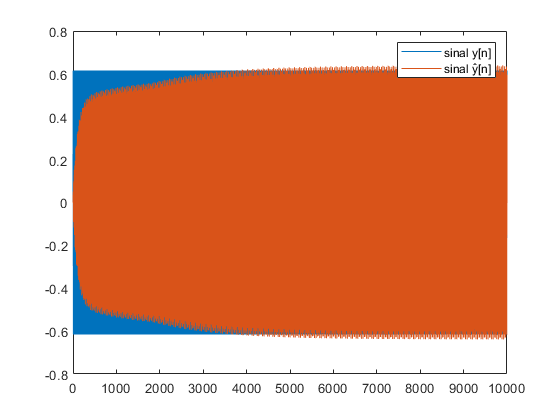

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);
figure()
plot(y)
hold on
plot(y_chapeu)
legend("sinal y[n]", "sinal ŷ[n]")
hold off

O sinal y_chapeu convergiu para o sinal y.

Observando a Potência do Erro de saída. 

    O erro de saída pode ser definido como a diferença entre o

    y_chapeu, que é a saída do filtro adaptativo H_chapeu que tenta estimar H.

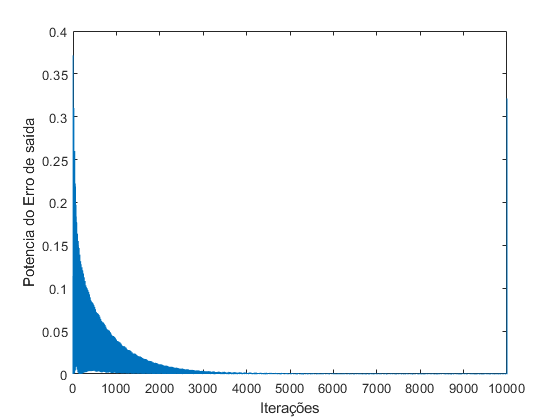

erroSaida = y - y_chapeu;
pot_erroSaida = erroSaida.*erroSaida;
figure()
plot(pot_erroSaida);
ylabel("Potencia do Erro de saída")
xlabel("Iterações")

O erro de saida possui um comportamento senoidal pois as diferenças entre os sinais y e y_chapeu estão

principalmente nos picos e vales dos sinais.

O Erro de saída tende a zero, como era esperado pois vimos que y_chapeu tende para y.

Sinais de erro 

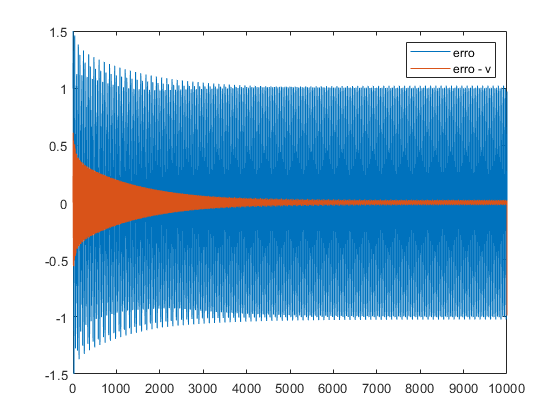

figure()
plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

ylim([-1.5 1.5])

No início o sinal de erro e a diferença entre este e o sinal v[n] mostram a etapa de adaptação do filtro.

Em regime permanente os sinais ficam estáveis com uma diferença pequena entre eles. 

Convergencia de coeficientes

    Pelo fato de o sinal x possuir apenas uma harmonica, o filtro H real ter dois coeficientes

    e o filtro H_chapeu que estamos estimando também ter dois coeficientes, espera-se que

    o filtro H_chapeu tenda para H, logo os coeficientes de H_chapeu serão iguais aos de H.

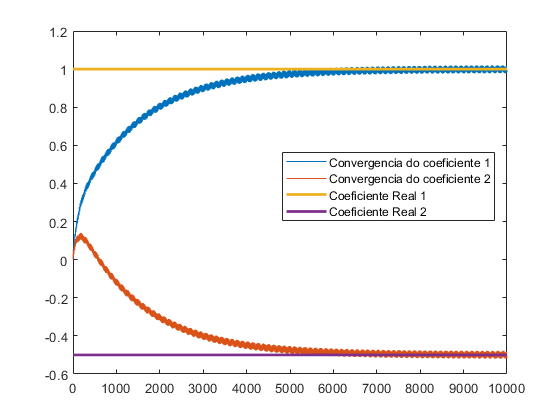

figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)], 'LineWidth',2)
plot([0 N],[h(2) h(2)], 'LineWidth',2)
legend("Convergencia do coeficiente 1"...
    ,"Convergencia do coeficiente 2" ...
    ,"Coeficiente Real 1"...
    ,"Coeficiente Real 2")
set(legend,...
    'Position',[0.504166675288052 0.473412724588283 0.380357134235757 0.165476185934884]);
hold off

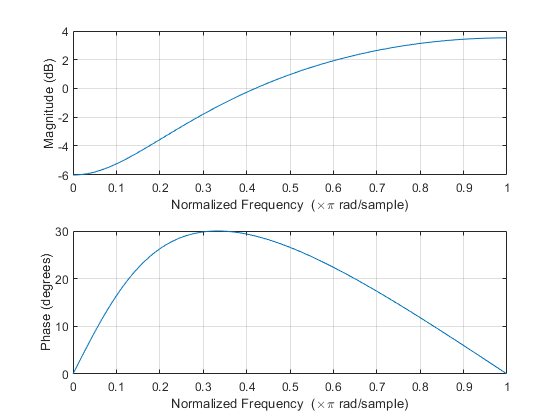

figure()
freqz(h,1)

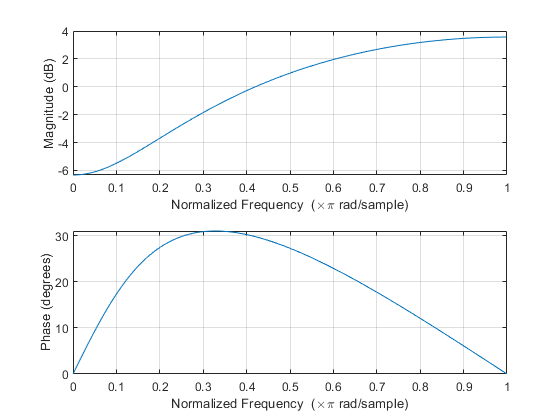

figure()
freqz(W(:,end))

## 3 - Novo ω_0

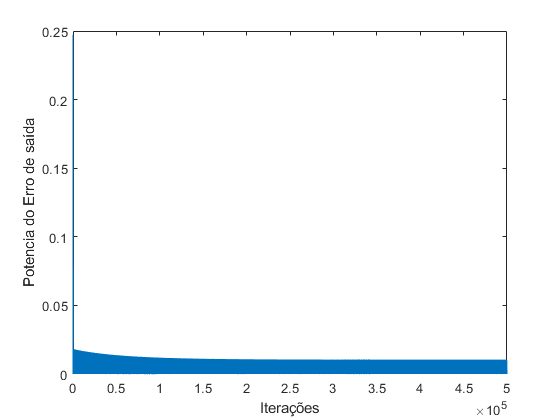

omega0 = pi/40;
N = 5e5;
n = (0:N-1);

x = sin(omega0*n);
v = cos(omega1*n);

y = filter(h,1,x);
d = y + v;

mu = 0.01;
[W, erro, y_chapeu] = lms(x, d, M, mu);

erroSaida = y - y_chapeu;
pot_erroSaida = erroSaida.*erroSaida;
figure()
plot(pot_erroSaida);
ylabel("Potencia do Erro de saída")
xlabel("Iterações")

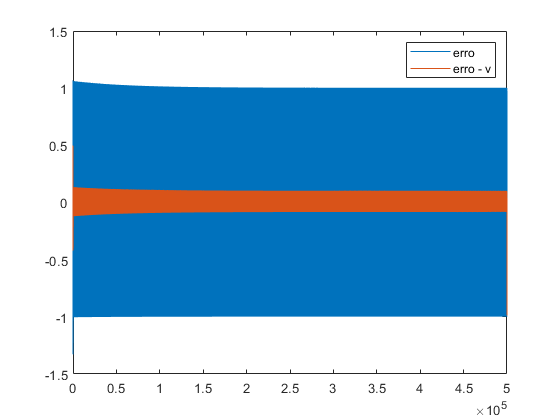


figure()
plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

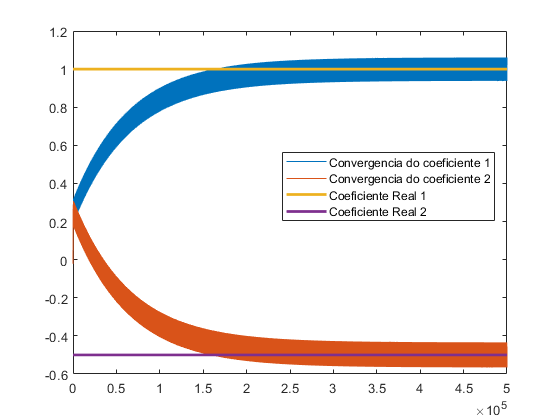


figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)], 'LineWidth',2)
plot([0 N],[h(2) h(2)], 'LineWidth',2)
legend("Convergencia do coeficiente 1"...
    ,"Convergencia do coeficiente 2" ...
    ,"Coeficiente Real 1"...
    ,"Coeficiente Real 2")
set(legend,...
    'Position',[0.504166675288052 0.473412724588283 0.380357134235757 0.165476185934884]);
hold off

Na situação em que omega0 é um valor muito pequeno, foi necessário um número muito maior

de iterações para que o algoritmo LMS convergisse, e não apenas isso, o erro em regime 

permanente ficou maior; a flutuação em torno do valor de convergência é bem maior que

no caso analisado anteriormente. 

Aumentar o passo de adaptação torna essa flutuação em torno da resposta ainda maior:

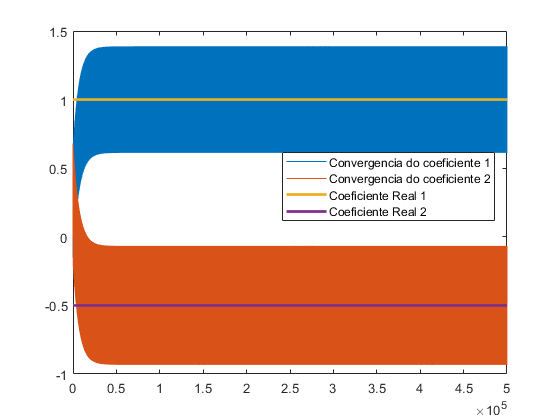

mu = 0.1;
[W, ~, ~] = lms(x, d, M, mu);
figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)], 'LineWidth', 2)
plot([0 N],[h(2) h(2)], 'LineWidth', 2)
legend("Convergencia do coeficiente 1"...
    ,"Convergencia do coeficiente 2" ...
    ,"Coeficiente Real 1"...
    ,"Coeficiente Real 2")
set(legend,...
    'Position',[0.504166675288052 0.473412724588283 0.380357134235757 0.165476185934884]);
hold off

## 4 - Filtro com 3 coeficientes

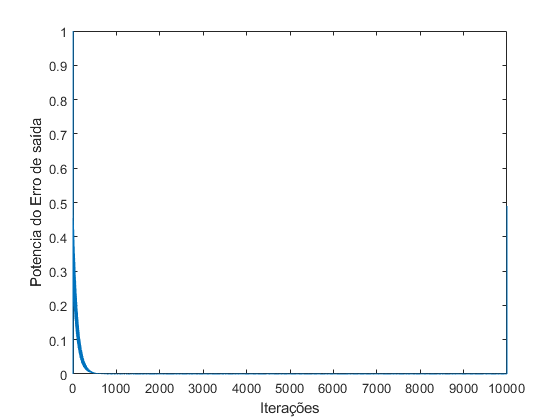

omega0 = pi/2;
omega1 = pi/20;
N = 1e4;
n = (0:N-1);
x = sin(omega0*n);
v = cos(omega1*n);
h = [1 -0.5 0.3];

y = filter(h,1,x);
d = y + v;

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);

erroSaida = y - y_chapeu;
pot_erroSaida = erroSaida.*erroSaida;
figure()
plot(pot_erroSaida);
ylabel("Potencia do Erro de saída")
xlabel("Iterações")

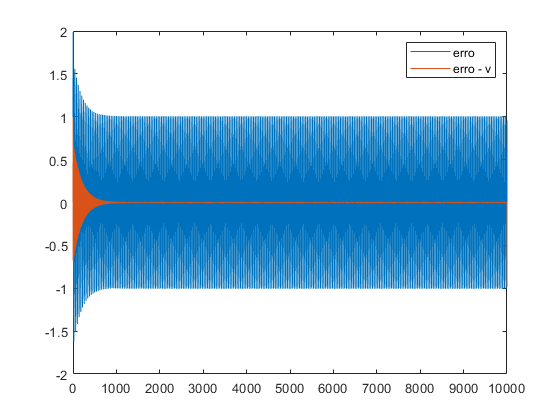

figure()
plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

Por algum motivo a resposta do filtro adaptativo ficou melhor do que a anterior quando H só tinha 2 coefs.

Temos que pensar porque isso acontece. 

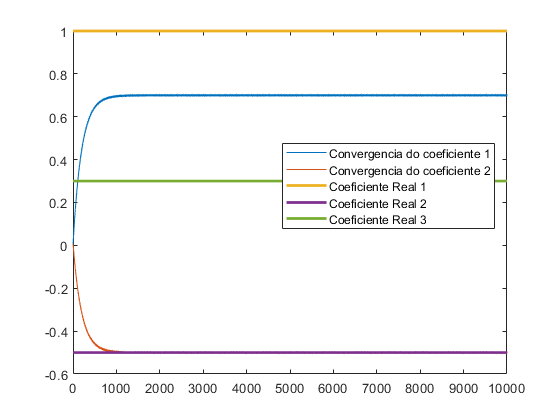

figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)], 'LineWidth',2)
plot([0 N],[h(2) h(2)], 'LineWidth',2)
plot([0 N],[h(3) h(3)], 'LineWidth',2)
legend("Convergencia do coeficiente 1"...
    ,"Convergencia do coeficiente 2" ...
    ,"Coeficiente Real 1"...
    ,"Coeficiente Real 2" ...
    ,"Coeficiente Real 3")
set(legend,...
    'Position',[0.504166675288052 0.473412724588283 0.380357134235757 0.165476185934884]);
hold off

Nesta situação, o número de coeficientes do H_chapeu não igual ao de H, portanto os 

coeficientes de um não irão coincidir também, mesmo que a resposta para a frequencia 

omega0 seja igual. 

Os coeficientes de convergência esperados para o filtro adaptativo H_chapeu são:

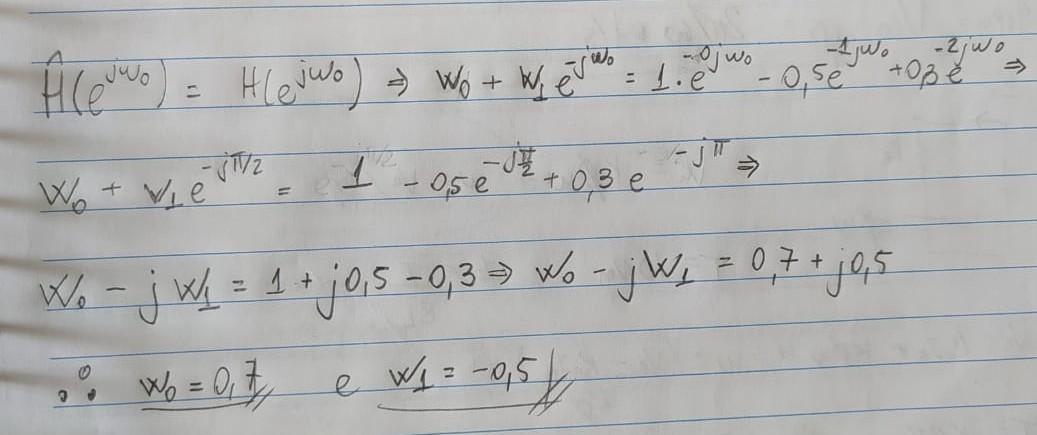

## 5 - Ganho dos filtros H e W

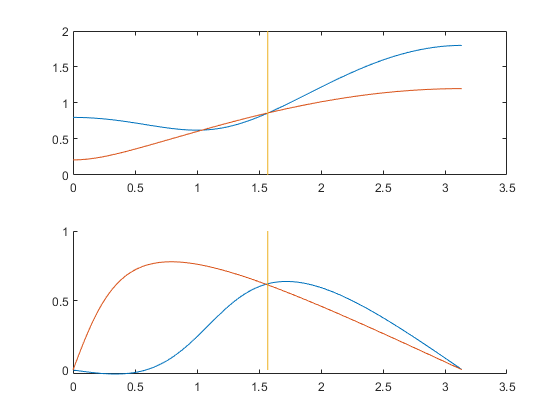

[H, omeguinha] = freqz(h);
[Wzao, omeguinhaW] = freqz(W(:,end));

figure()
subplot(2,1,1)
plot(omeguinha, abs(H))
hold on
plot(omeguinhaW, abs(Wzao))
plot([omega0 omega0], [0 2])
hold off
subplot(2,1,2)
hold on
plot(omeguinha, angle(H))
plot(omeguinhaW, angle(Wzao))
plot([omega0 omega0], [0 1])
hold off

Mesmo que o filtro H_chapeu não tenda para o H real, ele consegue realizar a função de neutralizar

o eco pois a resposta em frequência dos dois sistemas é muito próxima para a frequência de interesse.

## 6 - Sinal x[n] modificado

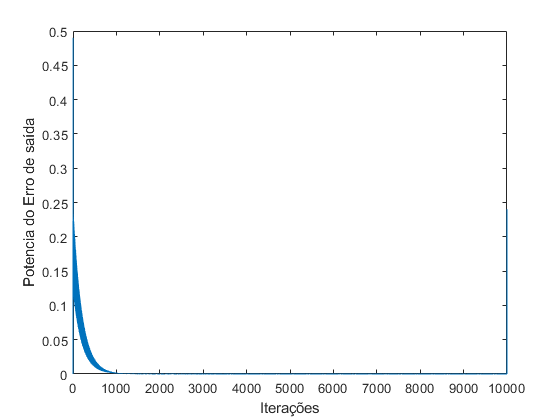

omega0 = pi/2;
omega1 = pi/20;
N = 1e4;
n = (0:N-1);
x = sin(omega0*n) + 0.3*sin(3*omega0*n);
v = cos(omega1*n);
h = [1 -0.5 0.3];

y = filter(h,1,x);
d = y + v;

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);

erroSaida = y - y_chapeu;
pot_erroSaida = erroSaida.*erroSaida;
figure()
plot(pot_erroSaida);
ylabel("Potencia do Erro de saída")
xlabel("Iterações")

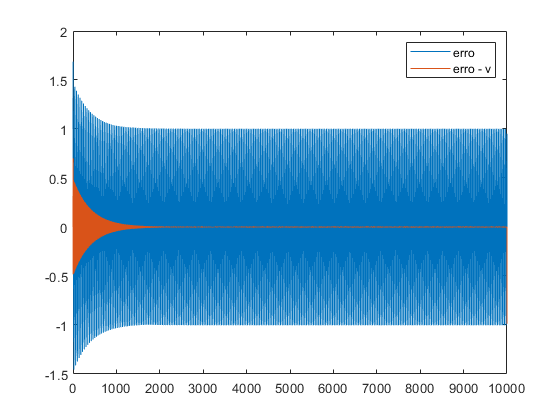

figure()
plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

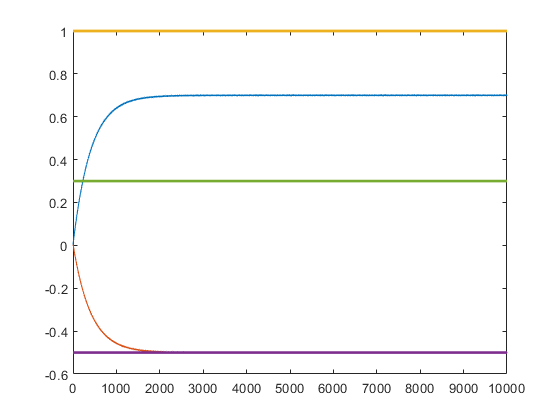

figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)], 'LineWidth',2)
plot([0 N],[h(2) h(2)], 'LineWidth',2)
plot([0 N],[h(3) h(3)], 'LineWidth',2)
hold off

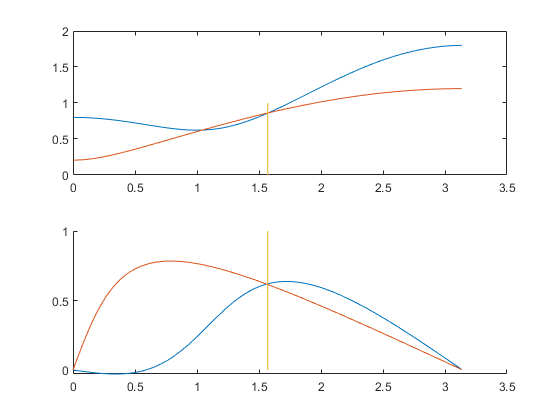


[H, omeguinha] = freqz(h);
[Wzao, omeguinhaW] = freqz(W(:,end));

figure()
subplot(2,1,1)
plot(omeguinha, abs(H))
hold on
plot(omeguinhaW, abs(Wzao))
plot([omega0 omega0], [0 1])
hold off
subplot(2,1,2)
hold on
plot(omeguinha, angle(H))
plot(omeguinhaW, angle(Wzao))
plot([omega0 omega0], [0 1])
hold off

A resposta nesta situação é idêntica à resposta vista no caso anterior pois no tempo discreto

a frequência 3*omega0 rebate para a frequência omega0 (para omega0 = pi/2), 

então o sistema enxerga apenas uma harmonica, 

que é omega0 = pi/2. 